clear; close all;
syms x0 y0 z1 d m

## Compute Bezier curves

figure;
axis equal
hold on
viscircles([0.35, 0.5; 0.65 0.5],[0.0675/2 0.0675/2],'LineStyle','-','Color','black');
rectangle('position',[0 0 1 1])

xlim([-0.1 1.1])
ylim([-0.1 1.1])

### Section 1

Starting point

q0 = [0;0];
v0 = [1;1];

End point

q3 = [0.5;0.5];
v3 = [1;1];

r1 = 0.2;
q1 = q0 + v0*r1;
r2 = -1/2;
q2 = q3 + v3*r2;

B = @(u,q0,q1,q2,q3) (1-u).^3.*q0 + 3*(1-u).^2.*u.*q1 + 3*(1-u).*u.^2.*q2 + u.^3.*q3;
xy1 = B(0:0.01:1,q0,q1,q2,q3);

plot(q1(1), q1(2), 'b.', 'markersize', 10);
plot(q2(1), q2(2), 'b.', 'markersize', 10);
plot([q0(1),q1(1)],[q0(2),q1(2)],'-g')
plot([q2(1),q3(1)],[q2(2),q3(2)],'-g')

plot(xy1(1,:), xy1(2,:), '-r')

### Section 2

q0 = q3;
v0 = v3;

q3 = [0.8;0.5];
v3 = [0;1];

r1 =0.3;
q1 = q0 + v0*r1;
r2 =0;
q2 = q3 + v3*r2;

B = @(u,q0,q1,q2,q3) (1-u).^3.*q0 + 3*(1-u).^2.*u.*q1 + 3*(1-u).*u.^2.*q2 + u.^3.*q3;
xy1 = B(0:0.01:1,q0,q1,q2,q3);

plot(q1(1), q1(2), 'b.', 'markersize', 10);
plot(q2(1), q2(2), 'b.', 'markersize', 10);
plot([q0(1),q1(1)],[q0(2),q1(2)],'-g')
plot([q2(1),q3(1)],[q2(2),q3(2)],'-g')

plot(xy1(1,:), xy1(2,:), '-r')

### Section 3

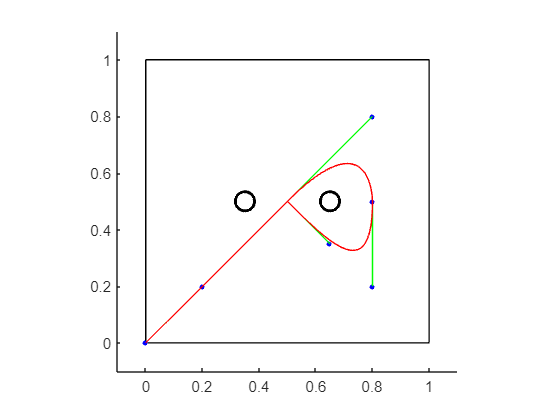

q0 = q3;
v0 = v3;

q3 = [0.5;0.5];
v3 = [-1;1];

r1 =-0.3;
q1 = q0 + v0*r1;
r2 =-0.15;
q2 = q3 + v3*r2;

B = @(u,q0,q1,q2,q3) (1-u).^3.*q0 + 3*(1-u).^2.*u.*q1 + 3*(1-u).*u.^2.*q2 + u.^3.*q3;
xy1 = B(0:0.01:1,q0,q1,q2,q3);

plot(q1(1), q1(2), 'b.', 'markersize', 10);
plot(q2(1), q2(2), 'b.', 'markersize', 10);
plot([q0(1),q1(1)],[q0(2),q1(2)],'-g')
plot([q2(1),q3(1)],[q2(2),q3(2)],'-g')

plot(xy1(1,:), xy1(2,:), '-r')